# MATLAB + SageMaker Blog Outline 

Rachel Johnson, 2023

This script summarizs the workflow for the MATLAB + SageMaker Blog Post demo, and describes the functions and objects included in the folder. 

## Summary

In this scenario, we want to classify faults in a pump that is streaming data from operational machines, then display the results in a web app dashboard. We have access to a large repository of labeled data generated from a Simulink simulation -- `SensorData`** -- **which has 3 possible fault types in various possible combinations (i.e., 1 health + 7 faulty states). Because we had a model of the system, and faults were rare in operation, we can take advantage of simulated data to train our algorithm. The model can be tuned to match operational data from our real pump using [Parameter Estimation](https://www.mathworks.com/discovery/parameter-estimation.html).

Because the full dataset is quite large*, we will start by creating a **prototype** of our classifier model on our desktop. We will extract features from a subset of the full dataset using the Diagnostic Feature Designer, and then compare the performance of several classifier models using the Classification Learner. 

Once we're happy with accuracy, we can generate MATLAB functions from these apps that will allow us to **scale up** the feature extraction and model training on the larger dataset using SageMaker compute resources.

Once we have our model trained on the full dataset, we want to **deploy** it in operation and connect to a dashboard that will display live data streaming from our pump. We will deploy the feature extraction function and classifier to a SageMaker endpoint, which we will connect to a MATLAB Web App dashboard that connects to data streaming from S3.

**Note that we do not acutally have a very large dataset for this example that would require extra compute resources -- but we should "fake" it for the blog post, since this would be a more realistic use case. We will discuss using a subset of SensorData for the prototyping workflow, even though this isn't necessary. (The alternative way would be to take a subset of SensorData for prototyping, e.g., 10-20% of the data -- I have not tried this though)*

## Part 0: System preparation

#### Add MATLAB code to path

thisFolder = fileparts(which('PumpCoolingSystem.mlx'));
assert(~isempty(thisFolder), "please cd to example folder");
rootFolder = fullfile(thisFolder, '..', '..');
addpath(fullfile(rootFolder, "matlab"));

#### Set up Python venv that has sagemaker & docker SDKs

sagemaker.pyenv(thisFolder);

Creating venv - /local-ssd/ralcock/github.com/mathworks/Machine-Learning-with-MATLAB-and-Amazon-Sagemaker-Demo/examples/PumpCoolingSystem/sagemaker-env


## Part 1: Data preparation & Feature Extraction

- Generate data from Simulink & preprocess data (no code) --> `SensorData`

- Extract features using DFD --> `extractFeatures`, `extractFeaturesStreaming`, `FeatureData`

- `Upload training data into Amazon S3 for later usage`

load SensorData.mat

%diagnosticFeatureDesigner


In the Diagnostic Feature Designer app, open `DFDAppSession.mat` as a saved app session to see all the features already ranked. (Later, we can provide screenshots of the app workflow for the blog post). 

Then, export a function for the top 15 features. We'll use the streaming option later, when we want to deploy, so best to export both functions now.

 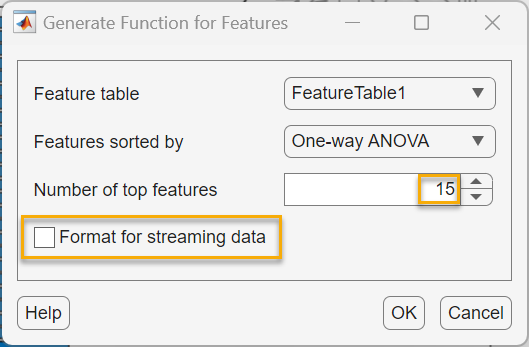

trainingData = extractFeaturesTraining(SensorData); % Extract training features using generated function
trainingData

trainingData = 240×16 table
    faultCode    flow_stats/Data_ClearanceFactor    flow_stats/Data_CrestFactor    flow_stats/Data_ImpulseFactor    flow_stats/Data_Mean    flow_stats/Data_RMS    flow_stats/Data_THD    pressure_stats/Data_CrestFactor    pressure_stats/Data_ImpulseFactor    pressure_stats/Data_Mean    pressure_stats/Data_RMS    pressure_stats/Data_THD    flow_ps_spec/Data_PeakAmp1    flow_ps_spec/Data_PeakAmp3    pressure_ps_spec/Data_PeakAmp1    pressure_ps_spec/Data_PeakAmp3
    _________    _______________________________    ___________________________    _____________________________    ____________________    __

## Part 2: Preprocessing

% Seperate feature and target columns

columnsToKeep = string(trainingData.Properties.VariableNames(1:end));
includedPredictorNames = columnsToKeep(2:end);
responseName = columnsToKeep(1:1);
trainPredictors = trainingData(:,includedPredictorNames);
summary(trainPredictors)

Variables:

    flow_stats/Data_ClearanceFactor: 240×1 double

        Values:

            Min        1.1397 
            Median     1.1752 
            Max        1.2721 

    flow_stats/Data_CrestFactor: 240×1 double

        Values:

            Min        1.1342 
            Median     1.1675 
            Max         1.258 

    flow_stats/Data_ImpulseFactor: 240×1 double

        Values:

            Min        1.1378 
            Median     1.1733 
            Max        1.2673 

    flow_stats/Data_Mean: 240×1 double

        Values:

            Min        34.185 
            Median     37.307 
            Max        38.459 

    flow_stats/Data_RMS: 240×1 double

        Values:

            Min        34.439 
            Median     37.498 
            Max        38.583 

    flow_stats/Data_THD: 240×1 double

        Values:

            Min       -16.596 
            Median


trainResponse = trainingData(:,responseName);
summary(trainResponse)

Variables:

    faultCode: 240×1 categorical

        Values:

            0         42   
            1         27   
            10        41   
            11        17   
            100       40   
            101       24   
            110       32   
            111       17   




% Scale the predictors numeric manually for the benefit of fitcauto and perhaps other models
trainPredictors(:,vartype("numeric")) = normalize(trainPredictors(:,vartype("numeric")));
summary(trainPredictors)

Variables:

    flow_stats/Data_ClearanceFactor: 240×1 double

        Values:

            Min        -1.3578
            Median    -0.30024
            Max         2.5891

    flow_stats/Data_CrestFactor: 240×1 double

        Values:

            Min        -1.3866
            Median    -0.30374
            Max         2.6374

    flow_stats/Data_ImpulseFactor: 240×1 double

        Values:

            Min        -1.3668
            Median    -0.27867
            Max         2.6091

    flow_stats/Data_Mean: 240×1 double

        Values:

            Min       -2.6438 
            Median    0.15554 
            Max         1.189 

    flow_stats/Data_RMS: 240×1 double

        Values:

            Min       -2.6645 
            Median     0.1813 
            Max        1.1904 

    flow_stats/Data_THD: 240×1 double

        Values:

            Min        -1.7856
            Median

## Part 3: Test building a ML model locally

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.48333 |    0.089609 |     0.48333 |     0.48333 |           23 |
|    2 | Best   |     0.40833 |    0.051081 |     0.40833 |     0.41499 |            4 |
|    3 | Best   |     0.39167 |    0.058081 |     0.39167 |     0.39167 |            1 |
|    4 | Accept |      0.7125 |    0.046191 |     0.39167 |       0.459 |           71 |
|    5 | Accept |     0.39167 |    0.050887 |     0.39167 |     0.39167 |            1 |
|    6 | Accept |     0.41667 |    0.057005 |     0.39167 |     0.39168 |            2 |
|    7 | Best   |     0.38333 |    0.047963 |     0.38333 |     0.38338 |            9 |
|    8 | Accept |    

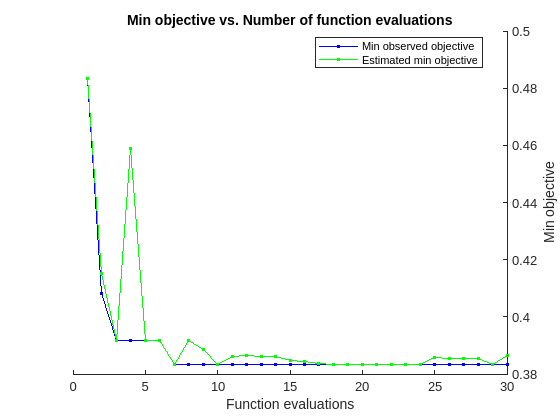

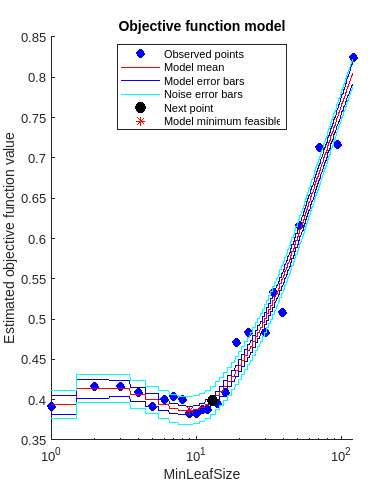


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 13.8585 seconds
Total objective function evaluation time: 1.5416

Best observed feasible point:
    MinLeafSize
    ___________

         9     

Observed objective function value = 0.38333
Estimated objective function value = 0.38658
Function evaluation time = 0.047963

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

         9     

Estimated objective function value = 0.38658
Estimated function evaluation time = 0.050899



% Set up and train a decision tree classifier
classifierModel = fitctree(...
    trainPredictors,...
    trainResponse,...
    OptimizeHyperparameters='auto');

## Part 4: Train the model in Amazon SageMaker

#### SageMaker session prepration

session = sagemaker.Session();

INFO:botocore.credentials:Found credentials in shared credentials file: ~/.aws/credentials


Define the IAM role that training jobs and deployed models will use.

role = sprintf("arn:aws:iam::%s:role/service-role/AmazonSageMaker-ExecutionRole-20210727T152745", session.AccountID);

#### Create a SageMaker estimator

Fitting this estimator will create a training job that willl run using a sagemaker training image based on image previously built and deployed to ECR. 

% Supply the image you built and pushed into Amazon ECR
trainingImage = sprintf("%s.dkr.ecr.%s.amazonaws.com/matlab-sagemaker-training-%s:latest", session.AccountID, session.BotoRegionName, "r"+version('-release'));

est = sagemaker.MATLABEstimator(...
    role, ...
    Image=trainingImage, ...
    Session=session, ...
    BaseJobName="PumpDecisionTreeMatlab", ...
    Environment = , ...
    TrainingFunction = @trainingFunction, ...
    HyperParameters = struct(), ... % named args to train_decision_tree
    InstanceType="ml.m5.large", ...
    MaxRunTime=minutes(10), ...    
    MaxWaitTime=minutes(20), ...
    UseSpotInstances=true);

Analysing files required by training function
Packaging required files as a mltbx
Moved mltbx to default bucket


#### Upload the training data into Amazon S3 bucket

writetable(trainingData,'pump_training_data.csv')
trainingDataLocation = "s3://"+session.DefaultBucket+"/cooling_system/input/pump_training";
copyfile("pump_training_data.csv", trainingDataLocation);

#### Submit SageMaker training job

est.fit(training=struct(Location=trainingDataLocation, ContentType="text/csv"))

INFO:sagemaker:Creating training-job with name: PumpDecisionTreeMatlab-2023-08-23-10-53-30-552


Error using session>_check_job_status
Python Error: UnexpectedStatusException: Error for Training job PumpDecisionTreeMatlab-2023-08-23-10-53-30-552: Failed. Reason: AlgorithmError: , exit code: 255

Error in session>wait_for_job (line 3588)

Error in 

2023-08-23 10:53:31 Starting - Starting the training job.
2023-08-23 10:53:44 Starting - Preparing the instances for training............
2023-08-23 10:54:51 Downloading - Downloading input data.....
2023-08-23 10:55:21 Training - Downloading the training image.............
2023-08-23 10:56:32 Training - Training image download completed. Training in progress...........
2023-08-23 10:57:28 Uploading - Uploading generated training model.
2023-08-23 10:57:38 Failed - Training job failed


trainingJob = est.LatestTrainingJob

## Part 5: Deploy the model as a real-time SageMaker Endpoint

predictor = est.deploy(role, "ClassificationTreeInferenceHandler", uint8(1), "ml.m5.large")

Building production server archive for ClassificationTreeInferenceHandler
Building docker image classificationtreeinferencehandler
Attempting To Pull Runtime Installer Image
r2023a: Pulling from matlab-runtime-utils/matlab-runtime-installer

□[1A□[2K
b549f31133a9: Pulling fs layer 
□[1B
□[1A□[2K
d6572f5f9ece: Pulling fs layer 
□[1B
□[1A□[2K
a1ff702e6a9f: Pulling fs layer 
□[1B□[3A□[2K
b549f31133a9: Downloading [>                                                  ]    277kB/27.5MB
□[3B□[2A□[2K
d6572f5f9ece: Downloading [>                                                  ]  535.6kB/225.6MB
□[2B□[1A□[2K
a1ff702e6a9f: Downloading [>                                                  ]  528.2kB/4.596GB
□[1B□[3A□[2K
b549f31133a9: Downloading [=====================>                             ]  11.88MB/27.5MB
□[3B□[2A□[2K
d6572f5f9ece: Downloading [==>                                                ]   10.1MB/225.6MB
□[2B□[1A□[2K
a1ff702e6a9f: Downloading [>                                    

predictor =   MATLABPredictor with properties:

    EndpointName: "classificationtreeinferencehandler-2023-05-23-02-24-19-948"


## Part 6: Test the endpoint

% select some test data
input = trainPredictors(10:19,:)

input = 10×15 table
    flow_stats/Data_ClearanceFactor    flow_stats/Data_CrestFactor    flow_stats/Data_ImpulseFactor    flow_stats/Data_Mean    flow_stats/Data_RMS    flow_stats/Data_THD    pressure_stats/Data_CrestFactor    pressure_stats/Data_ImpulseFactor    pressure_stats/Data_Mean    pressure_stats/Data_RMS    pressure_stats/Data_THD    flow_ps_spec/Data_PeakAmp1    flow_ps_spec/Data_PeakAmp3    pressure_ps_spec/Data_PeakAmp1    pressure_ps_spec/Data_PeakAmp3
    _______________________________    ___________________________    _____________________________    ____________________    ___________________    ___________________  



% calling sagemaker endpoint for inference
prediction = predictor.predict(input)

prediction = 10×1 table
    faultCode
    _________

       100   
         0   
       100   
         0   
       100   
         0   
       100   
       100   
       100   
       100   


## Part 7: Further possible integration

- Deploy `extractFeaturesStreaming` + `classifier` to Sagemaker endpoint (`deploy` function*)*

- Test endpoint with streaming data `SensorDataStreaming` (`predict` function)

- Deploy webapp dashboard + connect to endpoints. (*We need to understand kafka stream configuration + endpoints configuration to call them. We do not need to actually build this, we can just explain how to do it and show a screenshot of the app -- see app below. We can also provide some wording to explain the part about estimating remaining useful life, which is not part of this example but could be applied/trained in a similar way if needed).*

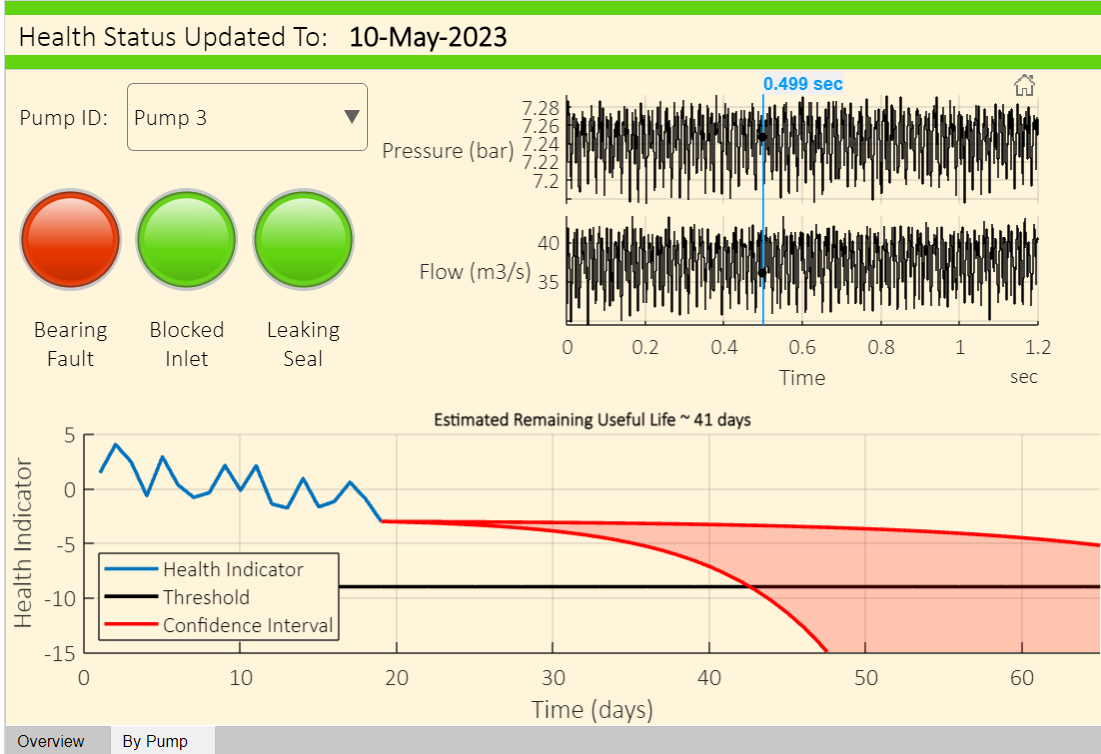

## Reference

### Objects

- `SensorData` -- A large* repository of historical sensor data, with labels.

- `SensorDataStreaming` -- Same as Sensordata, but no labels and all in one continuous timetable, which mimicks data streaming in live.

- `FeatureTable` - The output of `FeatureTable = extractFeaturesTraining(SensorData). `Saved mat file included for reference

- `classifier -` The output of `classifier = trainClassifier(FeatureTable). `Saved mat file included for reference. This is an bayesian optimized ensemble using `fitcensemble`.

### Functions

- `extractFeaturesTraining` - Generated code from Diagnostic Feature Designer app. Input is `SensorData` (i.e., historical data with labels). Output is a table of features with labels (`FeatureTable`), which is used for training a classifier.

- `extractFeaturesStreaming` - Generated code from Diagnostic Feature Designer app, optimized for streaming data. Input is a subset of `SensorDataStreaming`, a timetable of data that includes columns of Time, Flow, and Pressure. Output is a single row of features, which can be passed to the predict method of Classifier for inference. 

- `trainClassifier` - Generated from Classification Learner app. Input is a table of features with labels (i.e., the output of `extractFeaturesTraining`). Output is a trained model (`Classifier`).

### App Sessions

- `DFDAppSession` - A saved session from the Diagnostic Feature Designer app in MATLAB (for reference and screenshots)

- `CLAppSession` - A saved session from the Classification Learner app in MATLAB (for reference and screenshots)

**Note that we do not acutally have a very large dataset for this example that would require extra compute resources -- but we should "fake" it for the blog post, since this would be a more realistic use case. We will discuss using a subset of SensorData for the prototyping workflow, even though this isn't necessary. (The alternative way would be to take a subset of SensorData for prototyping, e.g., 10-20% of the data -- I have not tried this though)*

### Training Function

function trainingFunction(env, varargin)

%% Input data reading
trainingDataStore = tabularTextDatastore(...
    env.ChannelInputFolders.training, ...
    IncludeSubfolders=true, ...
    TextType="string");
trainingData = readall(trainingDataStore);

%% Pre-processing
columnsToKeep = string(trainingData.Properties.VariableNames(1:end));
includedPredictorNames = columnsToKeep(2:end);
responseName = columnsToKeep(1:1);
trainPredictors = trainingData(:,includedPredictorNames);
trainResponse = trainingData(:,responseName);
trainPredictors(:,vartype("numeric")) = normalize(trainPredictors(:,vartype("numeric")));

%% model training
model = fitctree(...
    trainPredictors,...
    trainResponse,...
    OptimizeHyperparameters='auto');

% Save the fitted model to /opt/ml/model/model.mat
save(fullfile(env.ModelFolder, 'model'), 'model');
end

% ------------------------------Supply training function end-----